# **1 - OPTION PRICING**

## **EXERCISE 1: Option Pricing**

Price a European Call Option with the following characteristics: 

### **SETUP**

% Initialize workspace
clc; clear; close all;

% Fix randomness
rng('default');   

% Add shared library folder
addpath(genpath(fullfile('..','..','lib')));

% Add project-specific folders
addpath(genpath('src'));
addpath(genpath('data'));
addpath(genpath('results'));

% Define paths
resultsPath = fullfile('results');
figuresPath = fullfile('results', 'figures');
srcPath = fullfile('src');
dataRawPath = fullfile('data', 'raw');
dataInterimPath = fullfile('data', 'interim');
dataProcessedPath = fullfile('data', 'processed');
libPath = fullfile('..','..','lib');

### **UPLOAD DATA**

% Load option parameters
load(fullfile(dataRawPath, 'params.mat'), 'params');

% Underlying future price
S0 = params.S0;

% Strike price
K = params.K;

% ttm zero rate
r = params.r;

% Yield
q = params.q;

% ttm
T = params.T;

% Volatility
sigma = params.sigma;

% Notional
notional = params.N;

% Knock-In Barrier
KI = params.KI;

% Compute the discount factor
B = exp(-r * T);

% Compute the forward price
F0 = S0 * exp((r - q) * T);

% Set the flag:
% For European Call = +1
% For European Put  = -1
optionType = 1;

### **POINT A**

Price the option, considering an underlying price equal to 1 Euro (i.e a derivative Notional of 1 Mln Euro): 

- via blkprice Matlab function; 

- with a CRR tree approach; 

- with a Monte-Carlo (MC) approach. 

% 1.
optionPriceBLK = EuropeanOptionClosed(S0, K, r, q, T, sigma, optionType);
fprintf('Closed formula price: %.4f €', optionPriceBLK);

Closed formula price: 0.0398 €

% 2.
nStep = 1e2;
optionPriceCRR = EuropeanOptionCRR(S0, K, r, q, T, sigma, nStep, optionType);
fprintf('CRR price: %.4f €', optionPriceCRR);

CRR price: 0.0398 €

% 3.
nSim = 1e6;
[optionPriceMC, ~] = EuropeanOptionMC(S0, K, r, q, T, sigma, nSim, optionType);
fprintf('Monte Carlo price: %.4f €', optionPriceMC);

Monte Carlo price: 0.0397 €

### **POINT B**

Focus on a call. Select M according to the criteria discussed, consider M:

- as the number of intervals in CRR;

- as the number of simulations in the MC.

% 1.
TuneCRR(S0, K, r, q, T, sigma, optionType);

CRR tuned steps: 16 
Black-76 Price: 0.0398 € 
CRR Price: 0.0397 € 
Error: 0.000046


% 2.
TuneMC(S0, K, r, q, T, sigma, optionType);

MC tuned steps: 524288 
Black-76 Price: 0.0398 € 
MC Price: 0.0398 € 
Error: 0.000090


### **POINT C**

Show that the numerical errors for a call rescale with M:

-  as $\frac{1}{M}$ for CRR;

-  as $\frac{1}{\sqrt{M}}$ for MC. 

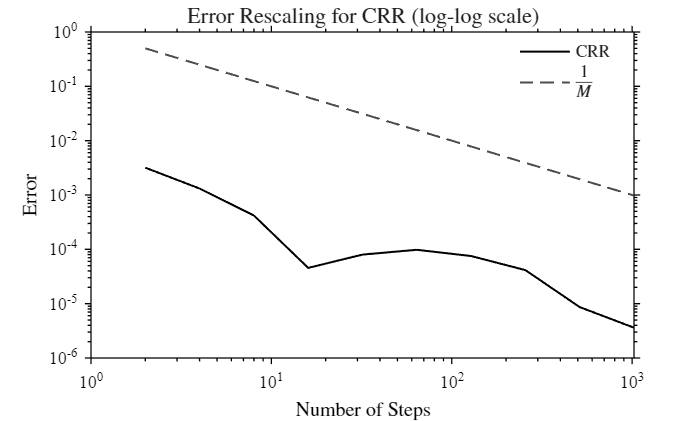

% 1. 
[nStep, errCRR] = PlotErrorCRR(S0, K, r, q, T, sigma);

figCRR = figure;
loglog(nStep, errCRR, '-', 'DisplayName', 'CRR'); hold on;
loglog(nStep, 1./nStep, '--', 'DisplayName', '$\frac{1}{M}$');
PlotUtils.setStyle();
PlotUtils.setLabels('Number of Steps', 'Error', ...
    'Error Rescaling for CRR (log-log scale)');
PlotUtils.setLegend();

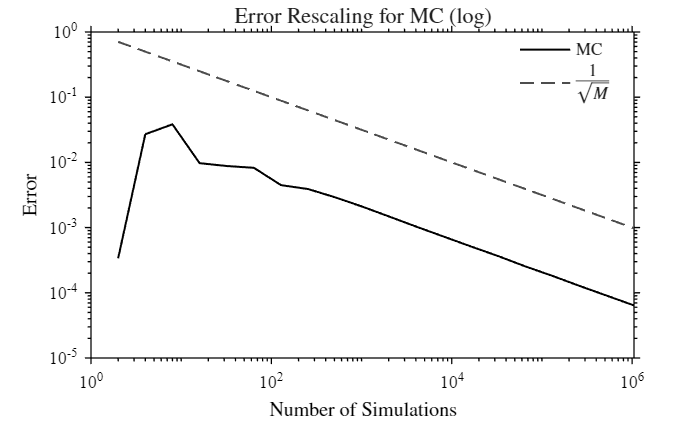

% 2. 
[nSim, errMC] = PlotErrorMC(S0, K, r, q, T, sigma);

figMC = figure;
loglog(nSim, errMC, '-', 'DisplayName', 'MC'); hold on;
loglog(nSim, 1./sqrt(nSim), '--', 'DisplayName', '$\frac{1}{\sqrt{M}}$');
PlotUtils.setStyle();
PlotUtils.setLabels('Number of Simulations', 'Error', ...
    'Error Rescaling for MC (log)');
PlotUtils.setLegend(); 

### **POINT D**

Price also a European Call Option with European barrier at 1.3 € (UP & IN) and same parameters with:

- closed formula;

- CRR;

- MC.

% 1.
optionPriceKIBLK = EuropeanOptionKIClosed(S0, K, KI, r, q, T, sigma);
fprintf('Closed formula price: %.4f €', optionPriceKIBLK);

Closed formula price: 0.0037 €

% 2.
nStep = 1e2;
optionPriceKICRR = EuropeanOptionKICRR(S0, K, KI, r, q, T, sigma, nStep);
fprintf('CRR price: %.4f €', optionPriceKICRR);

CRR price: 0.0037 €

% 3.
% WARNING: Slow execution, set to 1e3 to speed up but the approximation will be poor
nStep = 1e3;
nSim = 1e6;
optionPriceKIMC = EuropeanOptionKIMC(S0, K, KI, r, q, T, sigma, nStep, nSim);
fprintf('Monte Carlo formula price: %.4f €', optionPriceKIMC);

Monte Carlo formula price: 0.0036 €

### **POINT E**

For this barrier option, with the underlying price in the range 0.60 € and 1.20 €, plot the $\Gamma$ using:

- the closed formula;

- a numerical estimate.

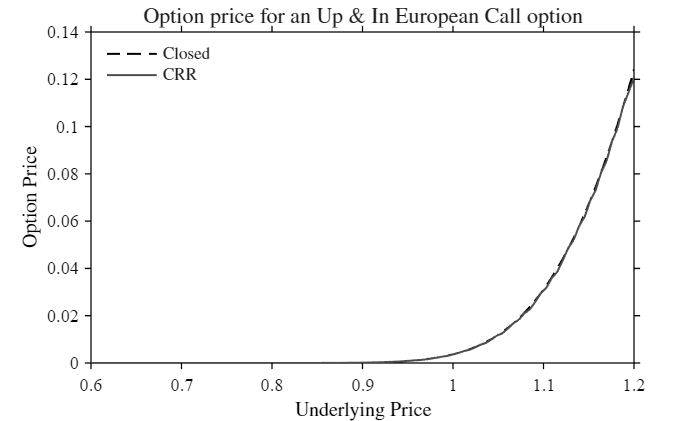

% Define range of prices
S0Range = linspace(0.6, 1.2, 100);

% 1.
gammaClosed = zeros(1, length(S0Range));
priceClosed = zeros(1, length(S0Range));
for i = 1:length(S0Range)
    priceClosed(i) = EuropeanOptionKIClosed(S0Range(i), K, KI, r, q, T, sigma);
    gammaClosed(i) = GammaKI(S0Range(i), K, KI, r, q, T, sigma, NaN, NaN, 1);
end

% 2. 
% Use CRR tree (MC is too slow)
nStep = 1e3;
gammaCRR = zeros(1, length(S0Range));
priceCRR = zeros(1, length(S0Range));
for i = 1:length(S0Range)
    priceCRR(i) = EuropeanOptionKICRR(S0Range(i), K, KI, r, q, T, sigma, nStep);
    gammaCRR(i) = GammaKI(S0Range(i), K, KI, r, q, T, sigma, NaN, nStep, 2);
end

% Plot prices 
figPrices = figure;
plot(S0Range, priceClosed, '--', 'DisplayName', 'Closed'); hold on;
plot(S0Range, priceCRR, '-', 'DisplayName', 'CRR');
PlotUtils.setStyle();
PlotUtils.setLabels('Underlying Price', 'Option Price', ...
    'Option price for an Up \& In European Call option');
PlotUtils.setLegend(); 

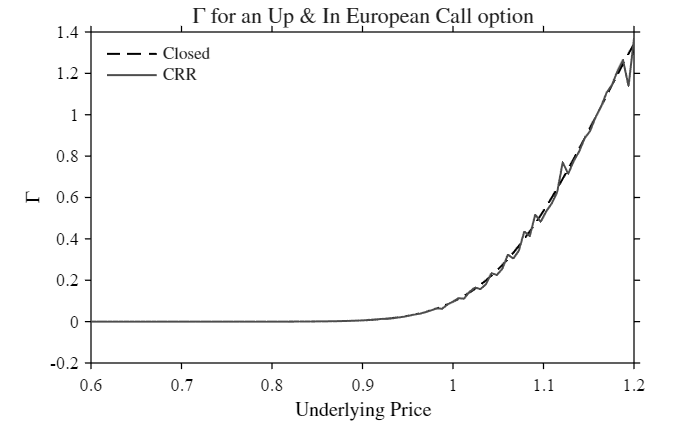

% Plot gamma
figGamma = figure;
plot(S0Range, gammaClosed, '--', 'DisplayName', 'Closed'); hold on;
plot(S0Range, gammaCRR, '-', 'DisplayName', 'CRR');
PlotUtils.setStyle();
PlotUtils.setLabels('Underlying Price', '$\Gamma$', ...
    '$\Gamma$ for an Up \& In European Call option');
PlotUtils.setLegend(); 

### **POINT F**

Does antithetic variables technique reduce MC error of point B? 

% MC
TuneMC(S0, K, r, q, T, sigma, optionType);

MC tuned steps: 524288 
Black-76 Price: 0.0398 € 
MC Price: 0.0397 € 
Error: 0.000090


% MC AV
TuneMCAV(S0, K, r, q, T, sigma, optionType);

MC AV steps: 262144 
Black-76 Price: 0.0398 € 
MC AV Price: 0.0398 € 
Error: 0.000072


### **POINT G**

Price also, with the Tree, a Bermudan option, where the holder has also the right to exercise the option at the end of every month, obtaining the stock at the strike price. 

% Price with built-in CRR (for comparison)
nStep = 3e2;
optionPriceCRR = BermudanOptionCRRExact(S0, K, r, q, T, sigma, nStep);
fprintf('Financial Toolbox CRR price: %.4f €', optionPriceCRR);

Financial Toolbox CRR price: 0.0400 €

% Price with CRR
nStepPerMonth = 1e2;
optionPriceCRR = BermudanOptionCRR(S0, K, r, q, T, sigma, nStepPerMonth);
fprintf('Implemented CRR price: %.4f €', optionPriceCRR);

Implemented CRR price: 0.0401 €

### **POINT H**

Pricing the Bermudan option, vary the dividend yield between 0% and 6% and compare with the corresponding European price.

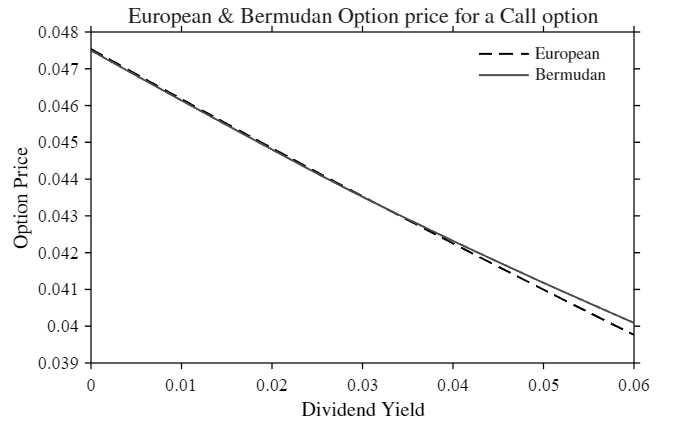

% Define dividend range
qRange = linspace(0.00, 0.06, 100);

% Compute European and Bermudan prices
europeanPrices = zeros(1, length(qRange));
bermudanPrices = zeros(1, length(qRange));
nStepPerMonth = 1e2;
for i = 1:length(qRange)
    europeanPrices(i) = EuropeanOptionClosed(S0, K, r, qRange(i), T, sigma, 1);
    bermudanPrices(i) = BermudanOptionCRR(S0, K, r, qRange(i), T, sigma, nStepPerMonth);
end

% Plot prices
figDividend = figure;
plot(qRange, europeanPrices, '--', 'DisplayName', 'European'); hold on;
plot(qRange, bermudanPrices, '-', 'DisplayName', 'Bermudan');
PlotUtils.setStyle();
PlotUtils.setLabels('Dividend Yield', 'Option Price', ...
    'European \& Bermudan Option price for a Call option');
PlotUtils.setLegend(); 